## Example 1: Window Functions

% Define window length and number of samples for fft
M = 64; % Choose an appropriate window length
n = -M/2 : M/2 - 1;
NFFT = 1024;

% Window functions
hanning_window = hanning(M);
hamming_window = hamming(M);
blackman_window = blackman(M);
blackmanharris_window = blackmanharris(M);
chebwin_window = chebwin(M, 30); % 30 dB sidelobe attenuation

% Plot the frequency response of each window
figure;

% Time domain representation subplot
subplot(2, 1, 1);
plot(n, hanning_window, n, hamming_window, n, blackman_window, n, blackmanharris_window, n, chebwin_window);
title('Time Domain Representation of Window Functions');
xlabel('Sample');
ylabel('Amplitude');
legend('Hanning', 'Hamming', 'Blackman', 'Blackman-Harris', 'Chebwin');
grid on;

% Frequency response subplot
subplot(2, 1, 2);

% Hanning window
X1 = fftshift(fft(hanning_window, NFFT));
Freq = (-NFFT/2 : NFFT/2 - 1) / NFFT;
Y1 = X1(1 : length(Freq)) / max(abs(X1));
mag_dB = 10 * log10(Y1);
plot(Freq, mag_dB, 'DisplayName', 'Hanning');

hold on;

% Hamming window
X2 = fftshift(fft(hamming_window, NFFT));
Y2 = X2(1 : length(Freq)) / max(abs(X2));
mag_dB2 = 10 * log10(Y2);
plot(Freq, mag_dB2, 'DisplayName', 'Hamming');


% Blackman window
X3 = fftshift(fft(blackman_window, NFFT));
Y3 = X3(1 : length(Freq)) / max(abs(X3));
mag_dB3 = 10 * log10(Y3);
plot(Freq, mag_dB3, 'DisplayName', 'Blackman');


% Blackman-Harris window
X4 = fftshift(fft(blackmanharris_window, NFFT));
Y4 = X4(1 : length(Freq)) / max(abs(X4));
mag_dB4 = 10 * log10(Y4);
plot(Freq, mag_dB4, 'DisplayName', 'Blackman-Harris');


% Chebwin window
X5 = fftshift(fft(chebwin_window, NFFT));
Y5 = X5(1 : length(Freq)) / max(abs(X5));
mag_dB5 = 10 * log10(Y5);
plot(Freq, mag_dB5, 'DisplayName', 'Chebwin');

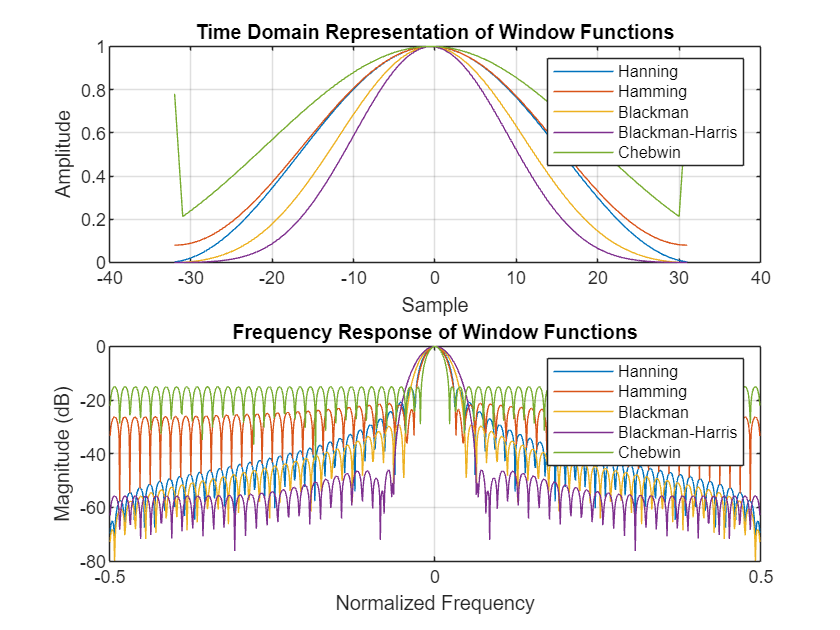


title('Frequency Response of Window Functions');
xlabel('Normalized Frequency');
ylabel('Magnitude (dB)');
legend('show');
grid on;
hold off;

## Example 2: Short-Time Fourier Transform ANALYSIS

clc
clear

% (a) Reading and resampling an audio file
filename = 'speechfiles/bbaq7a.wav'; 
[y, originalFs] = audioread(filename);
sound(y,originalFs)

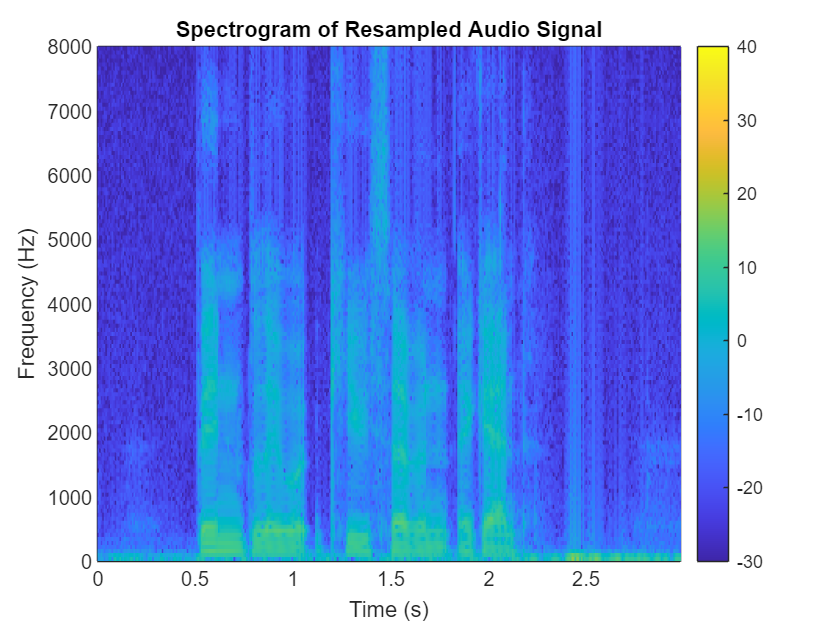

% Resample to 16kHz
targetFs = 16000; % Target sampling rate 
% originalFs = 25000 % original sampling rate
y_resampled = resample(y, targetFs, originalFs);
% Play the resampled audio
sound(y_resampled, targetFs);
% The resample function in MATLAB is used to change the sample rate of a signal. It is used to upsample or downsample audio signals. 

% (c) Analyzing the Time-Frequency representation
% Choose appropriate parameters
windowSize = 256;
overlapFactor = 0.5;
hammingWindow = hamming(windowSize);

% Apply STFT to the resampled signal
[X_stft, timeVector, freqVector] = stft_ece(y_resampled, hammingWindow, overlapFactor, targetFs);

% Plot the spectrogram
figure;
pl = pcolor(timeVector, freqVector, 10 * log10(abs(X_stft)));
set(pl, 'EdgeColor', 'none');
clim([-30, 40]);
title('Spectrogram of Resampled Audio Signal');
xlabel('Time (s)');
ylabel('Frequency (Hz)');
ylim([0 targetFs/2]);
colorbar;

## Example 3: Short-Time Fourier Transform SYNTHESIS

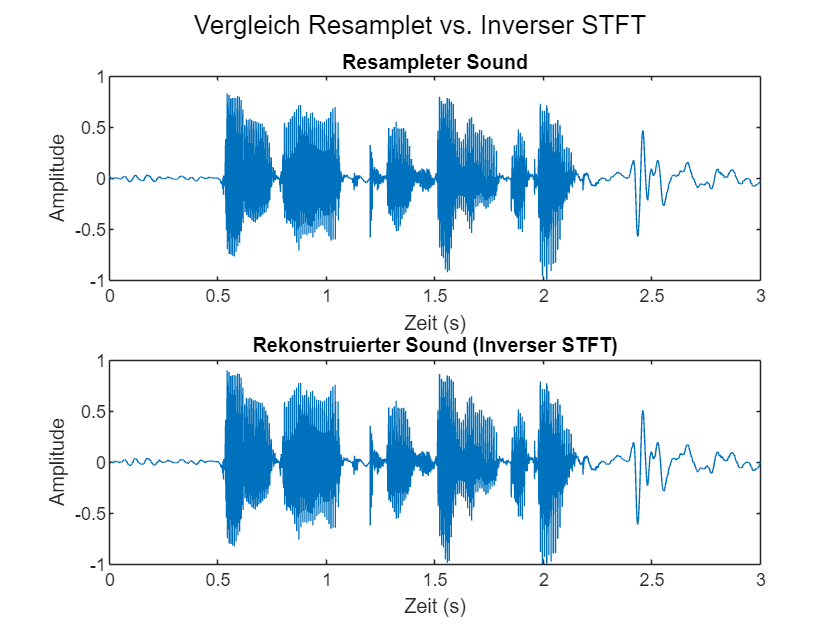

clc
clear

% readfile 
filename = 'speechfiles/bbaq7a.wav'; 
[y, originalFs] = audioread(filename);

% resample
targetFs = 16000;
y_resampled = resample(y, targetFs, originalFs);

% stft factors
windowSize = 256;
hammingWindow = hamming(windowSize);
overlapFactor = 0.5;

% stft
[X_stft, timeVector, freqVector] = stft_ece(y_resampled, hammingWindow, overlapFactor, targetFs);

%(A)

% Inverse Stft
[x_ifft] = istft_ece(X_stft, hammingWindow, overlapFactor);


%(B)

% Play sound
sound(x_ifft,targetFs)

% Plot 
figure;
subplot(2, 1, 1);
t_resampled = (0:length(y_resampled)-1) / targetFs;
plot(t_resampled, y_resampled);
title('Resampleter Sound');
xlabel('Zeit (s)');
ylabel('Amplitude');
ylim([-1,1]);

subplot(2, 1, 2);
t_reconstructed = (0:length(x_ifft)-1) / targetFs;
plot(t_reconstructed, x_ifft);
title('Rekonstruierter Sound (Inverser STFT)');
xlabel('Zeit (s)');
ylabel('Amplitude');
ylim([-1,1]);
sgtitle('Vergleich Resamplet vs. Inverser STFT');

## Example 4: The Notch Filter

clc
clear
%(A)

One Sinwave Disturbance

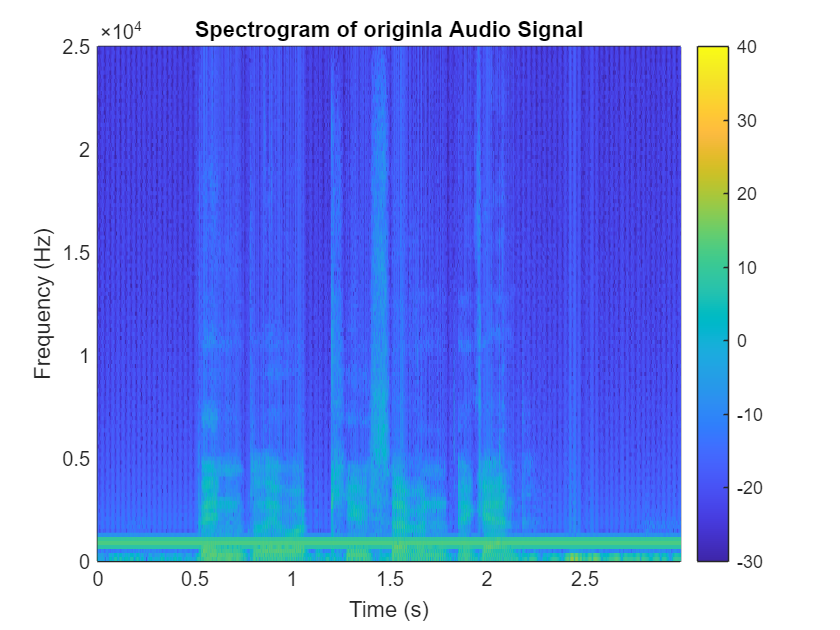

% Load and play audio signal speechPlusOneSinDist
[x1, fs1] = audioread('soundfiles/speechPlusOneSinDist.wav');
sound(x1,fs1)

% stft original speechPlusOneSinDist
windowSize = 256;
hammingWindow = hamming(windowSize);
overlapFactor = 0.5;
[X1_stft, timeVectorX1, freqVectorX1] = stft_ece(x1, hammingWindow, overlapFactor, fs1);

% Plot the spectrogram of the original speechPlusOneSinDist
figure;
plx1 = pcolor(timeVectorX1, freqVectorX1, 10 * log10(abs(X1_stft)));
set(plx1, 'EdgeColor', 'none');
clim([-30, 40]);
title('Spectrogram of originla Audio Signal');
xlabel('Time (s)');
ylabel('Frequency (Hz)');
ylim([0 fs1/2]);
colorbar;

% Disturbance at 800 Hz 

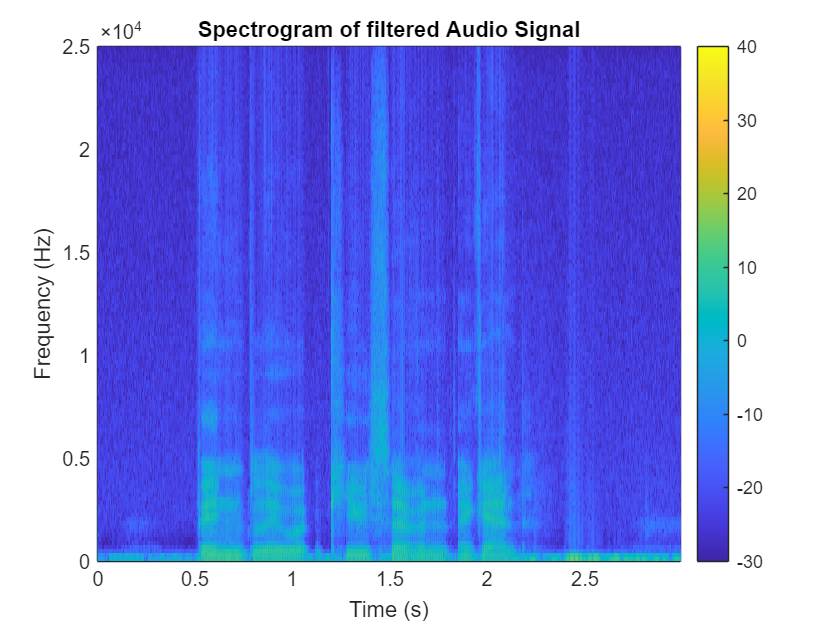

% Set parameters for the notch filter for speechPlusOneSinDist
desiredFrequencyX1 = 800;
radiusX1 = 0.9;  %radius for the poles

% Create poles and zeros for the notch filter  speechPlusOneSinDist
p1 = radiusX1 * exp(1j * 2 * pi * desiredFrequencyX1 / fs1);
z1 = exp(1i * 2 * pi * desiredFrequencyX1 / fs1);

% Create numerator and denominator polynomials  speechPlusOneSinDist
b1 = poly([z1, conj(z1)]);
a1 = poly([p1, conj(p1)]);

% Apply notch filter to the signal speechPlusOneSinDist
y1 = filter(b1, a1, x1);

% stft filtered speechPlusOneSinDist
[Y1_stft, timeVectorY1, freqVectorY1] = stft_ece(y1, hammingWindow, overlapFactor, fs1);

% Plot the spectrogram from the filtered speechPlusOneSinDist
figure;
ply1 = pcolor(timeVectorY1, freqVectorY1, 10 * log10(abs(Y1_stft)));
set(ply1, 'EdgeColor', 'none');
clim([-30, 40]);
title('Spectrogram of filtered Audio Signal');
xlabel('Time (s)');
ylabel('Frequency (Hz)');
ylim([0 fs1/2]);
colorbar;

%Filtered Sound from speechPlusOneSinDist
sound(y1,fs1)

Three Sinwave Disturbance

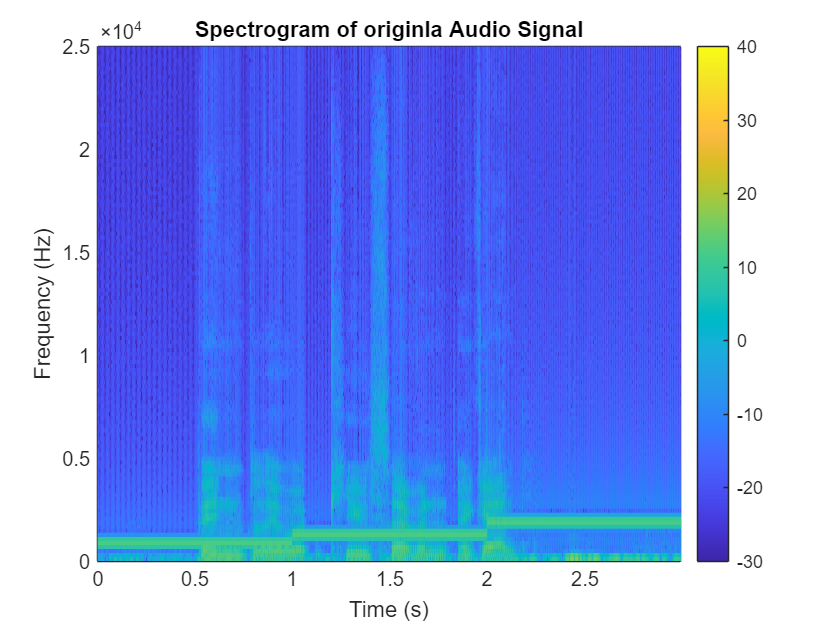

% Load and play audio signal speechPlusThreeSinDist
[x2, fs2] = audioread('soundfiles/speechPlusThreeSinDist.wav');
sound(x2,fs2)

% stft original speechPlusThreeSinDist
windowSize = 256;
hammingWindow = hamming(windowSize);
overlapFactor = 0.5;
[X2_stft, timeVectorX2, freqVectorX2] = stft_ece(x2, hammingWindow, overlapFactor, fs2);

% Plot the spectrogram of the original speechPlusThreeSinDist
figure;
plx2 = pcolor(timeVectorX2, freqVectorX2, 10 * log10(abs(X2_stft)));
set(plx2, 'EdgeColor', 'none');
clim([-30, 40]);
title('Spectrogram of originla Audio Signal');
xlabel('Time (s)');
ylabel('Frequency (Hz)');
ylim([0 fs1/2]);
colorbar;

% Disturbance at 800Hz, 1200Hz and 1800Hz

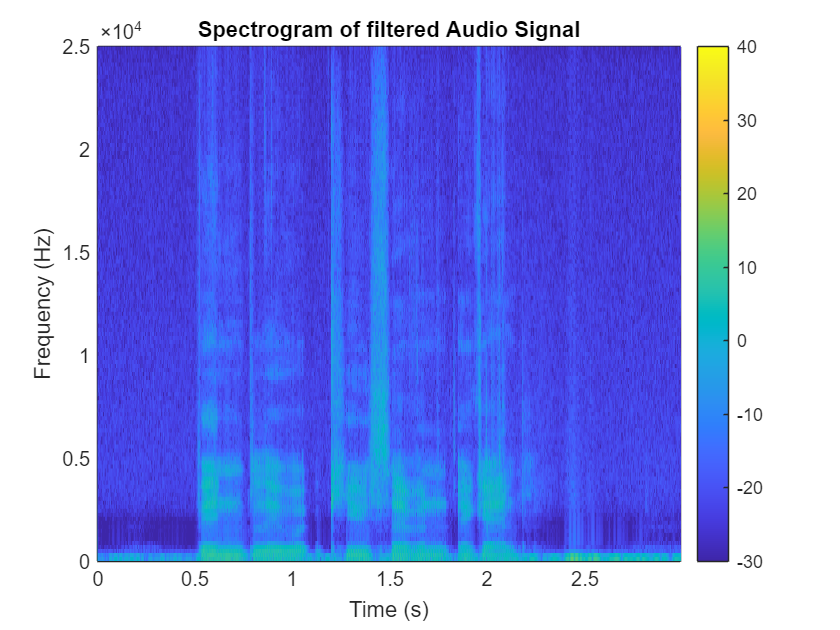

% Set parameters for the notch filter for speechPlusThreeSinDist
desiredFrequencyX2a = 800;
desiredFrequencyX2b = 1200;
desiredFrequencyX2c = 1800;
radiusX2 = 0.9;  %radius for the poles

% Create poles and zeros for the notch filter  speechPlusThreeSinDist
pa2 = radiusX2 * exp(1j * 2 * pi * desiredFrequencyX2a / fs2);
za2 = exp(1j * 2 * pi * desiredFrequencyX2a / fs2);

pb2 = radiusX2 * exp(1j * 2 * pi * desiredFrequencyX2b / fs2);
zb2 = exp(1j * 2 * pi * desiredFrequencyX2b / fs2);

pc2 = radiusX2 * exp(1j * 2 * pi * desiredFrequencyX2c / fs2);
zc2 = exp(1j * 2 * pi * desiredFrequencyX2c / fs2);

% Create numerator and denominator polynomials  speechPlusThreeSinDist
ba2 = poly([za2, conj(za2)]);
aa2 = poly([pa2, conj(pa2)]);

bb2 = poly([zb2, conj(zb2)]);
ab2 = poly([pb2, conj(pb2)]);

bc2 = poly([zc2, conj(zc2)]);
ac2 = poly([pc2, conj(pc2)]);

% Apply notch filter to the signal speechPlusThreeSinDist
ya2 = filter(ba2, aa2, x2);
yb2 = filter(bb2, ab2, ya2);
yc2 = filter(bc2, ac2, yb2);

% stft filtered speechPlusThreeSinDist
[Y2_stft, timeVectorY2, freqVectorY2] = stft_ece(yc2, hammingWindow, overlapFactor, fs2);

% Plot the spectrogram from the filtered speechPlusThreeSinDist
figure;
ply2 = pcolor(timeVectorY2, freqVectorY2, 10 * log10(abs(Y2_stft)));
set(ply2, 'EdgeColor', 'none');
clim([-30, 40]);
title('Spectrogram of filtered Audio Signal');
xlabel('Time (s)');
ylabel('Frequency (Hz)');
ylim([0 fs1/2]);
colorbar;

%Filtered Sound from speechPlusThreeSinDist
sound(yc2,fs2)

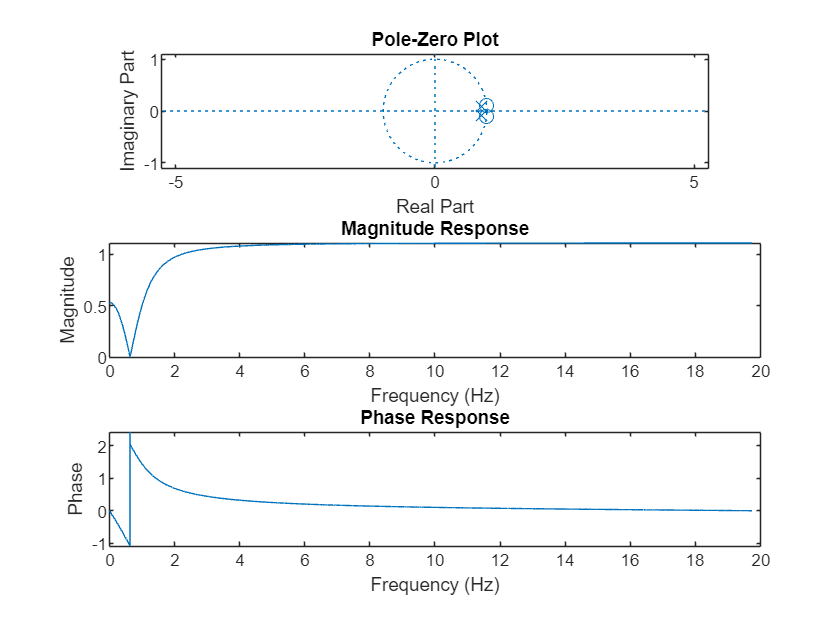

%(C)
% Plot the pole-zero plot
figure;
subplot(3,1,1);
zplane(b1, a1);
title('Pole-Zero Plot');

% Plot the magnitude response
subplot(3,1,2);
[h, w] = freqz(b1, a1, fs1);
plot(w*2*pi, abs(h));  
title('Magnitude Response');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

% Plot the phase response
subplot(3,1,3);
[h, w] = freqz(b1, a1, fs1);
phi = angle(h);
plot(w*2*pi, phi);
title('Phase Response');
xlabel('Frequency (Hz)');
ylabel('Phase');

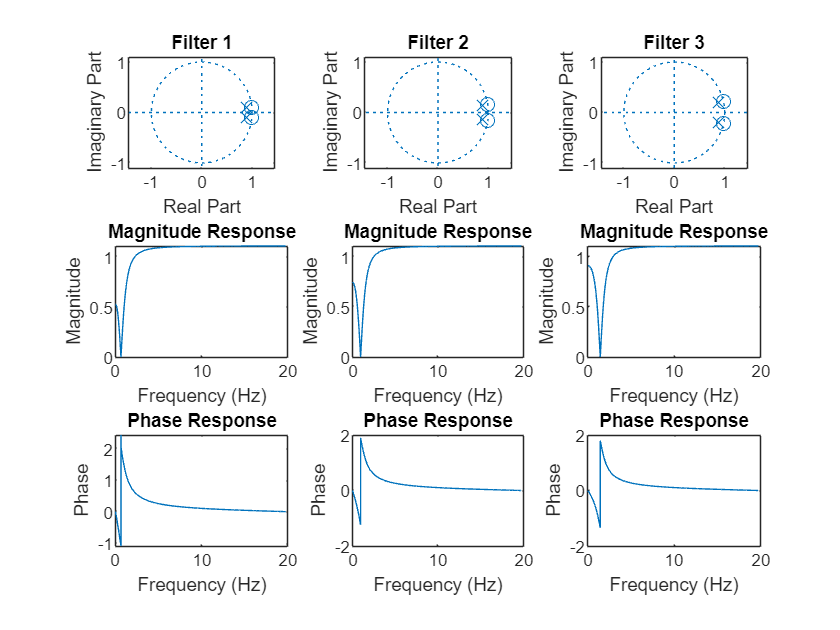

% Plot for Filter 1 (ba2, aa2)
figure;
subplot(3,3,1);
zplane(ba2, aa2);
title('Filter 1');

subplot(3,3,4);
[h1, w1] = freqz(ba2, aa2, fs1);
plot(w1*2*pi, abs(h1));
title('Magnitude Response');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

subplot(3,3,7);
[h1, w1] = freqz(ba2, aa2, fs1);
phi = angle(h1);
plot(w1*2*pi, phi);
title('Phase Response');
xlabel('Frequency (Hz)');
ylabel('Phase');

% Plot for Filter 2 (bb2, ab2)
subplot(3,3,2);
zplane(bb2, ab2);
title('Filter 2');

subplot(3,3,5);
[h2, w2] = freqz(bb2, ab2, fs1);
plot(w2*2*pi, abs(h2));
title('Magnitude Response');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

subplot(3,3,8);
[h2, w2] = freqz(bb2, ab2, fs1);
phi = angle(h2);
plot(w2*2*pi, phi);
title('Phase Response');
xlabel('Frequency (Hz)');
ylabel('Phase');

% Plot for Filter 3 (bc2, ac2)
subplot(3,3,3);
zplane(bc2, ac2);
title('Filter 3');

subplot(3,3,6);
[h3, w3] = freqz(bc2, ac2, fs1);
plot(w3*2*pi, abs(h3));
title('Magnitude Response');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

subplot(3,3,9);
[h3, w3] = freqz(bc2, ac2, fs1);
phi = angle(h3);
plot(w3*2*pi, phi);
title('Phase Response');
xlabel('Frequency (Hz)');
ylabel('Phase');